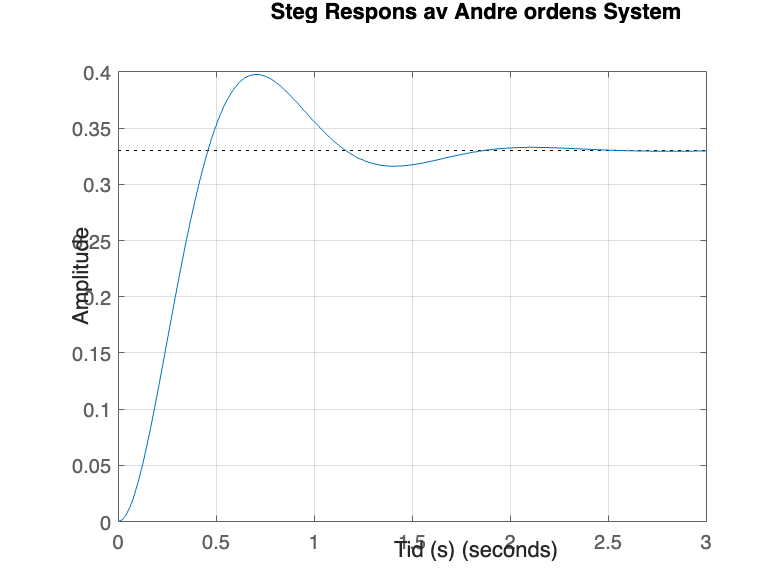

% Andreordens systemanalyse i MATLAB

% Parametere for systemet
K = 0.33;        % Gain
w = 5;            % Omega, udempet naturlig frekvens (rad/s)
c = 0.45;        % Zeta, dempningsforhold

% Andre ordens overføringsfunksjon
numerator = K * w^2;                     % Tellerpolynomet
denominator = [1, 2*c*w, w^2];           % Nevnerpolynomet
G = tf(numerator, denominator);          % Overføringsfunksjon

% Beregn karakteristiske tider og egenskaper
info = stepinfo(G);                      % Beregn systemegenskaper
overshoot = info.Overshoot;              % Oversving i prosent
riseTime = info.RiseTime;                % Stigningstid
peakTime = info.PeakTime;                % Toppunktstid
settlingTime = info.SettlingTime;        % Innsvingingstid

% Beregninger av dempet naturlig frekvens
w_d = w * sqrt(1 - c^2);                 % Dempet naturlig frekvens (rad/s)

% Symbolsk representasjon
syms s t
G_sym = K * (w^2) / (s^2 + 2*c*w*s + w^2); % Symbolsk overføringsfunksjon
M_sym = 1 / s;                            % Steginngang
Y_sym = G_sym * M_sym;                    % Systemutgang i Laplace
y_time = ilaplace(Y_sym);                 % Stegrespons i tidsdomenet

% Beregn statisk feil
e_inf = 1 / (1 + K);

% Beregn ytelsesmål basert på w og c
peakTime_calc = pi / w_d;               % Beregnet toppunktstid
overshoot_calc = exp(-pi * c / sqrt(1 - c^2)) * 100; % Beregnet oversving

% Finn poler og vurder stabilitet
poles = pole(G);

% Plot stegrespons
figure;
step(G);
title('Steg Respons av Andre ordens System');
xlabel('Tid (s)');
ylabel('Amplitude');
grid on;

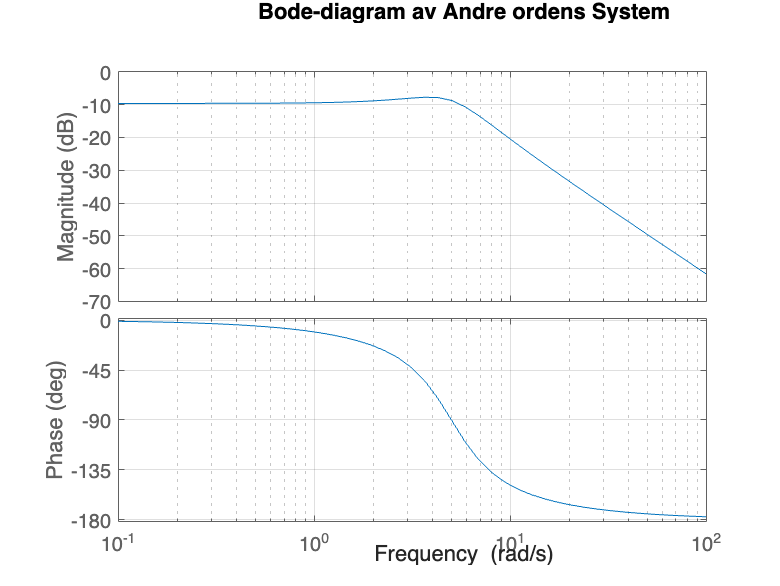


% Plot Bode-diagram
figure;
bode(G);
title('Bode-diagram av Andre ordens System');
grid on;


% Beregn forsterknings- og fasemargin
[GM, PM, Wcg, Wcp] = margin(G);

% Utskrift av resultater
fprintf('Systemegenskaper:\n');

Systemegenskaper:


fprintf('Gain (K): %.3f\n', K);

Gain (K): 0.330


fprintf('Naturlig frekvens (w): %.3f rad/s\n', w);

Naturlig frekvens (w): 5.000 rad/s


fprintf('Dempningsforhold (c): %.3f\n', c);

Dempningsforhold (c): 0.450


fprintf('Dempet naturlig frekvens (w_d): %.3f rad/s\n', w_d);

Dempet naturlig frekvens (w_d): 4.465 rad/s


fprintf('Stigningstid (Tr): %.3f sekunder\n', riseTime);

Stigningstid (Tr): 0.310 sekunder


fprintf('Toppunktstid (Tp): %.3f sekunder\n', peakTime);

Toppunktstid (Tp): 0.696 sekunder


fprintf('Beregnet Toppunktstid (Tp): %.3f sekunder\n', peakTime_calc);

Beregnet Toppunktstid (Tp): 0.704 sekunder


fprintf('Innsvingingstid (Ts): %.3f sekunder\n', settlingTime);

Innsvingingstid (Ts): 1.669 sekunder


fprintf('Oversving (OS): %.3f%%\n', overshoot);

Oversving (OS): 20.519%


fprintf('Beregnet Oversving (OS): %.3f%%\n', overshoot_calc);

Beregnet Oversving (OS): 20.535%


fprintf('Statisk feil (e_inf): %.3f\n', e_inf);

Statisk feil (e_inf): 0.752



fprintf('\nPoler:\n');


Poler:


disp(poles);

  -2.2500 + 4.4651i
  -2.2500 - 4.4651i



if all(real(poles) < 0)
    fprintf('Systemet er stabilt (alle poler har negativ realdel).\n');
else
    fprintf('Systemet er ustabilt (minst én pol har positiv eller null realdel).\n');
end

Systemet er stabilt (alle poler har negativ realdel).



fprintf('Forsterkningsmargin (GM): %.2f dB\n', 20*log10(GM));

Forsterkningsmargin (GM): Inf dB


fprintf('Fasemargin (PM): %.2f grader\n', PM);

Fasemargin (PM): Inf grader



fprintf('\nOverføringsfunksjon Y(s):\n');


Overføringsfunksjon Y(s):


disp(vpa(Y_sym, 3)); % Skriver ut Y(s)

$$\frac{8.25}{s\,\left(s^{2}+4.5\,s+25.0\right)}$$

fprintf('\nSteg respons i tidsdomenet, y(t):\n');


Steg respons i tidsdomenet, y(t):


disp(vpa(y_time, 3)); % Skriver ut y(t)

$$0.33-0.33\,{\mathrm{e}}^{-2.25\,t}\,\left(\cos\left(4.47\,t\right)+0.504\,\sin\left(4.47\,t\right)\right)$$